clc
clear all
close all

% x-axis: GREEN
% y-axis: BLUE
% z-axis: RED

% DH transformation matrix var
theta1 = 0;
beta = atand(0.024/0.128);
theta2 = -28.4;
theta3 = -5.05;
theta4 = -23.4;

T0 = eye(4);

% first transformation (i=1)
T1 = T0 * threeDTransform(0, 0, 7.7, theta1) 

T1 =     1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000    7.7000
         0         0         0    1.0000


x_dir1 = T1(1:3, 1)*5;
y_dir1 = T1(1:3, 2)*5;
z_dir1 = T1(1:3, 3)*5;
center1 = T1(:, 4);

% frame change (i=2)
T2 = T1 * threeDTransform(-90, 0, 0, -90) 

T2 =          0    1.0000         0         0
         0         0    1.0000         0
    1.0000         0         0    7.7000
         0         0         0    1.0000


x_dir2 = T2(1:3, 1)*5;
y_dir2 = T2(1:3, 2)*5;
z_dir2 = T2(1:3, 3)*5;
center2 = T2(:, 4);

% second transformation (i=3)
T3 = T2 * threeDTransform(0, 0, 0, -beta-theta2)

T3 =     0.3054    0.9522         0         0
         0         0    1.0000         0
    0.9522   -0.3054         0    7.7000
         0         0         0    1.0000


T3 = T3 * threeDTransform(0, 13, 0, 0)

T3 =     0.3054    0.9522         0    3.9698
         0         0    1.0000         0
    0.9522   -0.3054         0   20.0790
         0         0         0    1.0000


x_dir3 = T3(1:3, 1)*5;
y_dir3 = T3(1:3, 2)*5;
z_dir3 = T3(1:3, 3)*5;
center3 = T3(:, 4);

% frame change (i=4)
T4 = T3 * threeDTransform(0, 0, 0, beta-90) 

T4 =    -0.8796    0.4756         0    3.9698
         0         0    1.0000         0
    0.4756    0.8796         0   20.0790
         0         0         0    1.0000


% T4 = T4 * threeDTransform(0, 0, 0, -90) 
x_dir4 = T4(1:3, 1)*5;
y_dir4 = T4(1:3, 2)*5;
z_dir4 = T4(1:3, 3)*5;
center4 = T4(:, 4);

% third transformation (i=5)
T5 = T4 * threeDTransform(0, 0, 0, theta3) 

T5 =    -0.9181    0.3963         0    3.9698
         0         0    1.0000         0
    0.3963    0.9181         0   20.0790
         0         0         0    1.0000


T5 = T5 * threeDTransform(0, 12.4, 0, 0)

T5 =    -0.9181    0.3963         0   -7.4147
         0         0    1.0000         0
    0.3963    0.9181         0   24.9937
         0         0         0    1.0000


x_dir5 = T5(1:3, 1)*5;
y_dir5 = T5(1:3, 2)*5;
z_dir5 = T5(1:3, 3)*5;
center5 = T5(:, 4);

% fourth transformation (i=6)
T6 = T5 * threeDTransform(0, 0, 0, theta4) 

T6 =    -1.0000   -0.0009         0   -7.4147
         0         0    1.0000         0
   -0.0009    1.0000         0   24.9937
         0         0         0    1.0000


T6 = T6 * threeDTransform(0, 12.6, 0, 0) 

T6 =    -1.0000   -0.0009         0  -20.0147
         0         0    1.0000         0
   -0.0009    1.0000         0   24.9828
         0         0         0    1.0000


x_dir6= T6(1:3, 1)*5;
y_dir6 = T6(1:3, 2)*5;
z_dir6 = T6(1:3, 3)*5;
center6 = T6(:, 4);

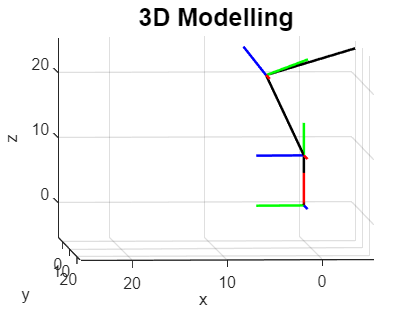

min_lim = -20;
max_lim = 40;

figure
% base frame (i=0)
plot3([0 5], [0 0], [0 0], 'LineWidth', 1.5, 'Color', 'g')
hold on
plot3([0 0], [0 5], [0 0], 'LineWidth', 1.5, 'Color', 'b')
hold on
plot3([0 0], [0 0], [0 5], 'LineWidth', 1.5, 'Color', 'r')
hold on

plot3([0 center1(1)], [0, center1(2)], [0, center1(3)], 'LineWidth', 1.5, 'Color', 'black')

% first transformation (i=1)
plot3([center1(1) center1(1)+x_dir1(1)], [center1(2) center1(2)+x_dir1(2)], [center1(3) center1(3)+x_dir1(3)], 'LineWidth', 1.5, 'Color', 'g')
hold on
plot3([center1(1) center1(1)+ y_dir1(1)], [center1(2) center1(2)+y_dir1(2)], [center1(3) center1(3)+y_dir1(3)], 'LineWidth', 1.5, 'Color', 'b')
hold on
plot3([center1(1) center1(1)+ z_dir1(1)], [center1(2) center1(2)+z_dir1(2)], [center1(3) center1(3)+z_dir1(3)], 'LineWidth', 1.5, 'Color', 'r')
hold on

% change frame! (i=2)
plot3([center2(1) center2(1)+x_dir2(1)], [center2(2) center2(2)+x_dir2(2)], [center2(3) center2(3)+x_dir2(3)], 'LineWidth', 1.5, 'Color', 'g')
hold on
plot3([center2(1) center2(1)+ y_dir2(1)], [center2(2) center2(2)+y_dir2(2)], [center2(3) center2(3)+y_dir2(3)], 'LineWidth', 1.5, 'Color', 'b')
hold on
plot3([center2(1) center2(1)+ z_dir2(1)], [center2(2) center2(2)+z_dir2(2)], [center2(3) center2(3)+z_dir2(3)], 'LineWidth', 1.5, 'Color', 'r')
hold on

plot3([center2(1) center3(1)], [center2(2) center3(2)], [center2(3) center3(3)], 'LineWidth', 1.5, 'Color', 'black')

% second transformation (i=3)
% plot3([center3(1) center3(1)+x_dir3(1)], [center3(2) center3(2)+x_dir3(2)], [center3(3) center3(3)+x_dir3(3)], 'LineWidth', 1.5, 'Color', 'g')
% hold on
% plot3([center3(1) center3(1)+y_dir3(1)], [center3(2) center3(2)+y_dir3(2)], [center3(3) center3(3)+y_dir3(3)], 'LineWidth', 1.5, 'Color', 'b')
% hold on
% plot3([center3(1) center3(1)+z_dir3(1)], [center3(2) center3(2)+z_dir3(2)], [center3(3) center3(3)+z_dir3(3)], 'LineWidth', 1.5, 'Color', 'r')
% hold on

% change frame! (i=4)
plot3([center4(1) center4(1)+x_dir4(1)], [center4(2) center4(2)+x_dir4(2)], [center4(3) center4(3)+x_dir4(3)], 'LineWidth', 1.5, 'Color', 'g')
hold on
plot3([center4(1) center4(1)+ y_dir4(1)], [center4(2) center4(2)+y_dir4(2)], [center4(3) center4(3)+y_dir4(3)], 'LineWidth', 1.5, 'Color', 'b')
hold on
plot3([center4(1) center4(1)+ z_dir4(1)], [center4(2) center4(2)+z_dir4(2)], [center4(3) center4(3)+z_dir4(3)], 'LineWidth', 1.5, 'Color', 'r')
hold on

plot3([center4(1) center5(1)], [center4(2) center5(2)], [center4(3) center5(3)], 'LineWidth', 1.5, 'Color', 'black')

% third transformation (i=5)
plot3([center5(1) center5(1)+x_dir5(1)], [center5(2) center5(2)+x_dir5(2)], [center5(3) center5(3)+x_dir5(3)], 'LineWidth', 1.5, 'Color', 'g')
hold on
plot3([center5(1) center5(1)+y_dir5(1)], [center5(2) center5(2)+y_dir5(2)], [center5(3) center5(3)+y_dir5(3)], 'LineWidth', 1.5, 'Color', 'b')
hold on
plot3([center5(1) center5(1)+z_dir5(1)], [center5(2) center5(2)+z_dir5(2)], [center5(3) center5(3)+z_dir5(3)], 'LineWidth', 1.5, 'Color', 'r')
hold on

plot3([center5(1) center6(1)], [center5(2) center6(2)], [center5(3) center6(3)], 'LineWidth', 1.5, 'Color', 'black')

% fourth transformation (i=6)
plot3([center6(1) center6(1)+x_dir6(1)], [center6(2) center6(2)+x_dir6(2)], [center6(3) center6(3)+x_dir6(3)], 'LineWidth', 1.5, 'Color', 'g')
hold on
plot3([center6(1) center6(1)+y_dir6(1)], [center6(2) center6(2)+y_dir6(2)], [center6(3) center6(3)+y_dir6(3)], 'LineWidth', 1.5, 'Color', 'b')
hold on
plot3([center6(1) center6(1)+z_dir6(1)], [center6(2) center6(2)+z_dir6(2)], [center6(3) center6(3)+z_dir6(3)], 'LineWidth', 1.5, 'Color', 'r')
hold on


xlim([min_lim max_lim])
ylim([min_lim max_lim])
zlim([min_lim max_lim])
xlabel('x')
ylabel('y')
zlabel('z')
grid on
title('3D Modelling', 'FontSize', 15)

function final_mat = threeDTransform(alpha, a, d, theta)
    final_mat = [cosd(theta),             -sind(theta),            0,            a;
                 sind(theta)*cosd(alpha), cosd(theta)*cosd(alpha), -sind(alpha), -sind(alpha)*d;
                 sind(theta)*sind(alpha), cosd(theta)*sind(alpha), cosd(alpha),  cosd(alpha)*d;
                 0,                       0,                       0,            1];
end